%% Diem-Linh Phan
%%3/26/26
%%community solar billing simulator
x=0:25:800

x =      0    25    50    75   100   125   150   175   200   225   250   275   300   325   350   375   400   425   450   475   500   525   550   575   600   625   650   675   700   725   750   775   800


planA= 15*x +25

planA =           25         400         775        1150        1525        1900        2275        2650        3025        3400        3775        4150        4525        4900        5275        5650        6025        6400        6775        7150        7525        7900        8275        8650        9025        9400        9775       10150       10525       10900       11275       11650       12025


planB = zeros(size(x))

planB =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


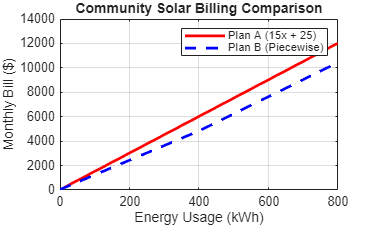

for i = 1:length(x)
    if x(i) <= 400
        planB(i) = 12*x(i) + 40;
    else
        planB(i) = 14*x(i) + (40 - 2 * 400);
    end
end

figure;
plot(x, planA, 'r', 'LineWidth', 2); hold on;
plot(x, planB, 'b--', 'LineWidth', 2);
grid on;

xlabel('Energy Usage (kWh)');
ylabel('Monthly Bill ($)');
title('Community Solar Billing Comparison');
legend('Plan A (15x + 25)', 'Plan B (Piecewise)');

## reflection prompts

%% Diem-Linh Phan
%%3/26/26
%%community solar billing simulator
function [start, inc, stop]=getUserInput()
start = input("enter the start value")
if start <0
    start = 0;
end
inc = input("enter the increment value")
if inc < 0
    inc = 25;
end
stop = input("enter the end value")
if stop < start || stop < 0
    stop = 800;
end
end
[a1,a2,a3] = getUserInput()

start = 12

incer = 12

stop = 2

Output argument "inc" (and possibly others) not assigned a value in the execution with "module1proj1>getUserInput" function.

x=a1:a2:a3
planA= 15*x +25
planB = zeros(size(x))
for i = 1:length(x)
    if x(i) <= 400
        planB(i) = 12*x(i) + 40;
    else
        planB(i) = 14*x(i) + (40 - 2 * 400);
    end
end

figure;
plot(x, planA, 'r', 'LineWidth', 2); hold on;
plot(x, planB, 'b--', 'LineWidth', 2);
grid on;

xlabel('Energy Usage (kWh)');
ylabel('Monthly Bill ($)');
title('Community Solar Billing Comparison');
legend('Plan A (15x + 25)', 'Plan B (Piecewise)');

%% Diem-Linh Phan
%%3/26/26
%%community solar billing simulator
function [start, inc, stop]=getUserInput()

Function 'getUserInput' has already been declared within this scope.

start = input("enter the start value")
if start <0
    start = 0;
end
inc = input("enter the increment value")
if inc <0
    inc = 25;
end
stop = input("enter the end value")
if stop < start || stop < 0
    stop = 800;
end
end
[a1,a2,a3] = getUserInput()
x=a1:a2:a3
planA= 15*x +25
planB = zeros(size(x))
for i = 1:length(x)
    if x(i) <= 400
        planB(i) = 12*x(i) + 40;
    else
        planB(i) = 14*x(i) + (40 - 2 * 400);
    end
end

figure;
plot(x, planA, 'r', 'LineWidth', 2); hold on;
plot(x, planB, 'b--', 'LineWidth', 2);
grid on;

xlabel('Energy Usage (kWh)');
ylabel('Monthly Bill ($)');
title('Community Solar Billing Comparison');
legend('Plan A (15x + 25)', 'Plan B (Piecewise)');
function createDataPairs (x,ba)
xBA= [x ; ba]
fid = fopen('Datapears01.txt','wt');
fprintf (fid, '%4.0f %4.0f \n', xba);
fclose(fid)
end